# Chapter 2: splitting integrators for ODEs

*Bram Lens - bram.lens@student.uantwerpen.be*

In this live script, we perform the numerical simulations in chapter 2 of the thesis.

clear; clc; tic; format long

## Problem initialisation

We consider four problems in this chapter: the harmonic oscillator `osc`, the mathematical pendulum `pen`, the Kepler problem `kep`, and the 3 body problem `3bp`.

% Initialisation of the problem
problem = "3bp";

% Data: using readData.m
data    = readData(problem);

## Exact solution

The exact solution to the integrable problems `osc` and `kep` can be computed using the function `exact`.

if data.integrable
    exact_solution = exact(problem);
end

## Numerical integration

We numerically integrate the chosen problem. To this aim, we implemented four integrators: forward Euler in `forwardEuler`, also known as explicit Euler, symplectic Euler using VT-splitting in `symplecticEuler`, Stormer-Verlet using VTV-splitting in `stormerVerlet`, and Yoshida's 4th order integrator in `yoshida4th`.

% Forward Euler
approx_fe = integrator(data, "fe");

% Symplectic Euler
approx_se = integrator(data, "se");

% Stormer-Verlet
approx_sv = integrator(data, "sv");

% Yoshida's 4th
approx_y4 = integrator(data, "y4");

## Energy computation

We now compute the energy associated to the numerical solutions using the function `energyCalc`.

% Exact energy
energy_ex   = data.H(data.initial(1:0.5*data.dim), data.initial(0.5*data.dim + 1: data.dim));

% Forward Euler's energy
energy_fe   = energyCalc(approx_fe, data);

% Symplectic Euler's energy
energy_se   = energyCalc(approx_se, data);

% Stormer-Verlet's energy
energy_sv   = energyCalc(approx_sv, data);

% Yoshida's 4th energy
energy_y4   = energyCalc(approx_y4, data);

## Computing other conserved quantities

The two $n$-body problems have angular momental as an additional conserved quantity on top of the total energy. We compute these quantities for both problems.

if problem == "kep"
    L0 = data.L(data.initial(1:2), data.initial(3:4));
    
    % Implementation of the vectors that will contain the angular momentum
    % at each iteration of the integrator
    amomentum_fe = sparse(1, data.N + 1); amomentum_fe(1) = L0;
    amomentum_se = sparse(1, data.N + 1); amomentum_se(1) = L0;
    amomentum_sv = sparse(1, data.N + 1); amomentum_sv(1) = L0;
    amomentum_y4 = sparse(1, data.N + 1); amomentum_y4(1) = L0;
    
    for index = 1:data.N + 1
        amomentum_fe(index) = data.L(approx_fe(1:2, index), approx_fe(3:4, index));
        amomentum_se(index) = data.L(approx_se(1:2, index), approx_se(3:4, index));
        amomentum_sv(index) = data.L(approx_sv(1:2, index), approx_sv(3:4, index));
        amomentum_y4(index) = data.L(approx_y4(1:2, index), approx_y4(3:4, index));
    end
    
elseif problem == "3bp"
    % Computing the angular momenta
    % Note: by our choice of initial values, the angular momentum's only
    % non-zero component is in its third component
    L0 = cross(data.initial(1:3), data.initial(10:12)) + ...
         cross(data.initial(4:6), data.initial(13:15)) + ...
         cross(data.initial(7:9), data.initial(16:18));
    Lfe = angMom3BP(approx_fe);
    Lse = angMom3BP(approx_se);
    Lsv = angMom3BP(approx_sv);
    Ly4 = angMom3BP(approx_y4);
end

## Plots

We now plot all the results computed above.

#### Trajectories

Remark: for the 3 body problem's trajectory according to forward Euler, zooming in is required to see more details.

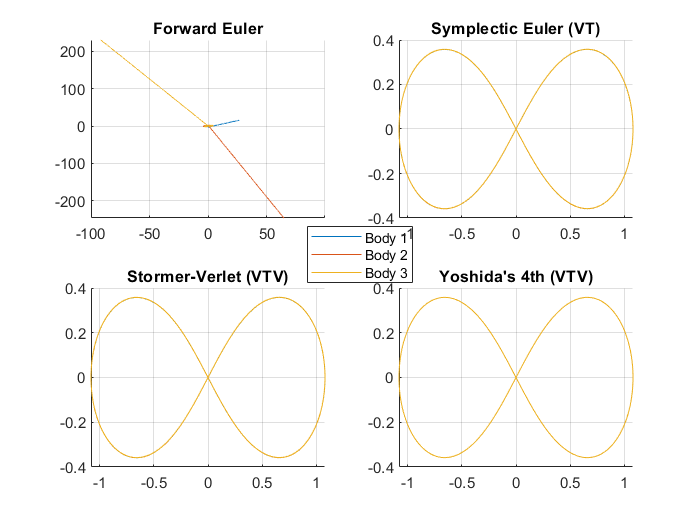

figure("Name", "Trajectories"); hold on; grid on; axis equal;
xlabel('q_x'); ylabel('q_y');

if problem == "osc"
    title('Trajectories: harmonic oscillator')
elseif problem == "pen"
    title('Trajectories: mathematical pendulum')
elseif problem == "kep"
    title('Trajectories: Kepler')
    p_star  = plot(0,0,'pentagram','MarkerSize',15,'MarkerEdgeColor',...
        '#C2921D','MarkerFaceColor','#EDB120');
    legend([p_star], ["star"])
elseif problem == "3bp"
    title('Trajectories: 3 body problem')
end

if data.integrable % osc, kep
    
    % Exact solution
    p_exact = plot(exact_solution(:,1), exact_solution(:,2), ":k", ...
        "LineWidth", 1.75);
    
    % Forward Euler approximation
    p_fe    = plot(approx_fe(1, :), approx_fe(2, :), "Color",...
        [220/255 20/255 60/255], "LineWidth", 1.15);

    % Symplectic Euler (VT) approximation
    p_se    = plot(approx_se(1, :), approx_se(2, :), "Color", ...
        [1 140/255 0],"LineWidth", 1.15);

    % Stormer-Verlet (VTV) approximation
    p_sv    = plot(approx_sv(1, :), approx_sv(2, :), "Color", ...
        [1 215/255 0],"LineWidth", 1.15);

    % Yoshida 4th approximation
    p_y4    = plot(approx_y4(1,:), approx_y4(2, :), "Color", [0 191/255 1],...
        "LineWidth", 1.15);

    % Initial point
    p_initial = scatter(data.initial(1), data.initial(2), 25, 'filled', "k");
    
    if problem == "osc"
        legend([p_exact, p_fe, p_se, p_sv, p_y4], ["Exact solution",...
            "Forward Euler", "Symplectic Euler (VT)", "Stormer-Verlet (VTV)",...
            "Yoshida's 4th"], "Location", "southoutside")
    elseif problem == "kep"
        legend([p_exact, p_fe, p_se, p_sv, p_y4], ["Exact solution",...
            "Forward Euler", "Symplectic Euler (VT)", "Stormer-Verlet (VTV)",...
            "Yoshida's 4th"], "Location", "southoutside")
    end
    
else
    if problem == "3bp"
        axis equal
    % Forward Euler trajectory
    subplot(2,2,1);
    title("Forward Euler")
    hold on; grid on;
    plot3bp_fe1 = plot3(approx_fe(1,:), approx_fe(2,:), approx_fe(3,:));
    plot3bp_fe2 = plot3(approx_fe(4,:), approx_fe(5,:), approx_fe(6,:));
    plot3bp_fe3 = plot3(approx_fe(7,:), approx_fe(8,:), approx_fe(9,:));
    %legend([plot3bp_fe1, plot3bp_fe2, plot3bp_fe3], ["Body 1", "Body 2",...
    %    "Body 3"])
    hold off
    
    % Symplectic Euler VT trajectory
    subplot(2,2,2);
    title("Symplectic Euler (VT)")
    hold on; grid on;
    plot3bp_se1 = plot3(approx_sv(1,:), approx_sv(2,:), approx_sv(3,:));
    plot3bp_se2 = plot3(approx_sv(4,:), approx_sv(5,:), approx_sv(6,:));
    plot3bp_se3 = plot3(approx_sv(7,:), approx_sv(8,:), approx_sv(9,:));
    %legend([plot3bp_se1, plot3bp_se2, plot3bp_se3], ["Body 1", "Body 2",...
    %    "Body 3"])
    hold off
    
    % Stormer-Verlet VTV trajectory
    subplot(2,2,3);
    title("Stormer-Verlet (VTV)")
    hold on; grid on;
    plot3(approx_sv(1,:), approx_sv(2,:), approx_sv(3,:));
    plot3(approx_sv(4,:), approx_sv(5,:), approx_sv(6,:));
    plot3(approx_sv(7,:), approx_sv(8,:), approx_sv(9,:));
    hold off
    
    % Yoshida's 4th trajectory
    subplot(2,2,4);
    title("Yoshida's 4th (VTV)")
    hold on; grid on;
    plot3(approx_y4(1,:), approx_y4(2,:), approx_y4(3,:));
    plot3(approx_y4(4,:), approx_y4(5,:), approx_y4(6,:));
    plot3(approx_y4(7,:), approx_y4(8,:), approx_y4(9,:));
    hold off
    
    Lgnd = legend([plot3bp_fe1, plot3bp_fe2, plot3bp_fe3], ["Body 1", ...
        "Body 2", "Body 3"]);
    Lgnd.Position(1) = 0.438;
    Lgnd.Position(2) = 0.46;
    
    elseif problem == "pen"
        % Forward Euler approximation
    p_fe    = plot(approx_fe(1, :), approx_fe(2, :), "Color",...
        [220/255 20/255 60/255], "LineWidth", 1.15);

    % Symplectic Euler (VT) approximation
    p_se    = plot(approx_se(1, :), approx_se(2, :), "Color", ...
        [1 140/255 0],"LineWidth", 1.15);

    % Stormer-Verlet (VTV) approximation
    p_sv    = plot(approx_sv(1, :), approx_sv(2, :), "Color", ...
        [1 215/255 0],"LineWidth", 1.15);

    % Yoshida 4th approximation
    p_y4    = plot(approx_y4(1,:), approx_y4(2, :), "Color", [0 191/255 1],...
        "LineWidth", 1.15);

    % Initial point
    p_initial = scatter(data.initial(1), data.initial(2), 25, 'filled', "k");
    
    legend([p_fe, p_se, p_sv, p_y4], ["Forward Euler", "Symplectic Euler (VT)", ...
        "Stormer-Verlet (VTV)","Yoshida's 4th"], "Location", "southoutside")
    end
end

#### Energy

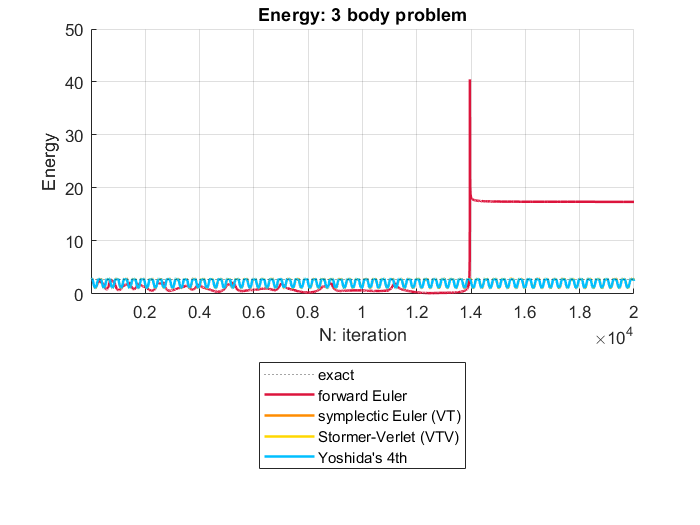

figure("Name", "Energies"); hold on; grid on;
xlim([1 data.N+1])
xlabel("N: iteration")
ylabel("Energy")

if problem == "osc"
    title("Energy: harmonic oscillator")
elseif problem == "pen"
    title("Energy: mathematical pendulum")
elseif problem == "kep"
    title("Energy: Kepler")
elseif problem == "3bp"
    title("Energy: 3 body problem")
end

% Exact energy
p_energy_ex = yline(energy_ex, ":k");

% Forward Euler's energy
p_energy_fe = plot(energy_fe, "Color", [220/255 20/255 60/255], "LineWidth", 1.5);

% Symplectic Euler's energy
p_energy_se = plot(energy_se, "Color", [1 140/255 0], "LineWidth", 1.5);

% Stormer-Verlet's energy
p_energy_sv = plot(energy_sv, "Color", [1 215/255 0], "LineWidth", 1.5);

% Yoshida's 4th energy
p_energy_y4 = plot(energy_y4, "Color", [0 191/255 1], "LineWidth", 1.5);

legend([p_energy_ex, p_energy_fe, p_energy_se, p_energy_sv, p_energy_y4], ...
    ["exact", "forward Euler", "symplectic Euler (VT)", "Stormer-Verlet (VTV)", ...
    "Yoshida's 4th"], "Location", "southoutside")
hold off

#### Angular momentum

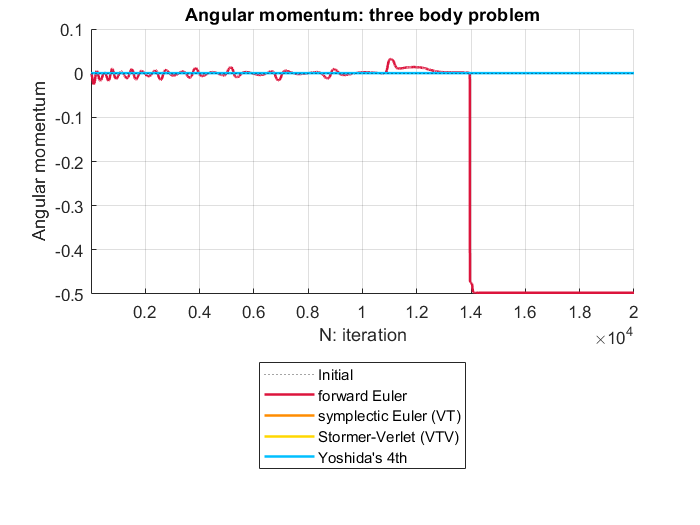

if problem == "kep"

    figure("Name", "Angular momentum"); hold on; grid on;
    xlim([1 data.N+1])
    xlabel("N: iteration")
    ylabel("Angular momentum")
    title("Angular momentum: Kepler")
    
    % Exact (initial) angular momentum
    p_amomentum_ex = yline(L0, ":k");
    
    % Forward Euler's angular momentum
    p_amomentum_fe = plot(amomentum_fe, "Color", [220/255 20/255 60/255], "LineWidth", 1.5);
    
    % Symplectic Euler (VT)'s angular momentum
    p_amomentum_se = plot(amomentum_se, "Color", [1 140/255 0], "LineWidth", 1.5);
    
    % Stormer-Verlet (VTV)'s angular momentum
    p_amomentum_sv = plot(amomentum_sv, "Color", [1 215/255 0], "LineWidth", 1.5);
    
    % Yoshida's 4th's angular momentum
    p_amomentum_y4 = plot(amomentum_y4, "Color", [0 191/255 1], "LineWidth", 1.5);
    
    legend([p_amomentum_ex, p_amomentum_fe, p_amomentum_se, p_amomentum_sv,...
        p_amomentum_y4], ["exact", "forward Euler", "symplectic Euler (VT)",...
        "Stormer-Verlet (VTV)", "Yoshida's 4th"], "Location", "southoutside")
    hold off
elseif problem == "3bp"
    
    figure("Name", "Angular momentum"); hold on; grid on;
    xlim([1 data.N+1])
    xlabel("N: iteration")
    ylabel("Angular momentum")
    title("Angular momentum: three body problem")
    
    % Exact (initial) angular momentum
    p_amomentum_ex = yline(L0(3,:), ":k");
    
    % Forward Euler's angular momentum
    p_amomentum_fe = plot(Lfe(3,:), "Color", [220/255 20/255 60/255], "LineWidth", 1.5);
    
    % Symplectic Euler (VT)'s angular momentum
    p_amomentum_se = plot(Lse(3,:), "Color", [1 140/255 0], "LineWidth", 1.5);
    
    % Stormer-Verlet (VTV)'s angular momentum
    p_amomentum_sv = plot(Lsv(3,:), "Color", [1 215/255 0], "LineWidth", 1.5);
    
    % Yoshida's 4th's angular momentum
    p_amomentum_y4 = plot(Ly4(3,:), "Color", [0 191/255 1], "LineWidth", 1.5);
    
    legend([p_amomentum_ex, p_amomentum_fe, p_amomentum_se, p_amomentum_sv,...
        p_amomentum_y4], ["Initial", "forward Euler", "symplectic Euler (VT)",...
        "Stormer-Verlet (VTV)", "Yoshida's 4th"], "Location", "southoutside")
    hold off
    
end

#### Relative errors

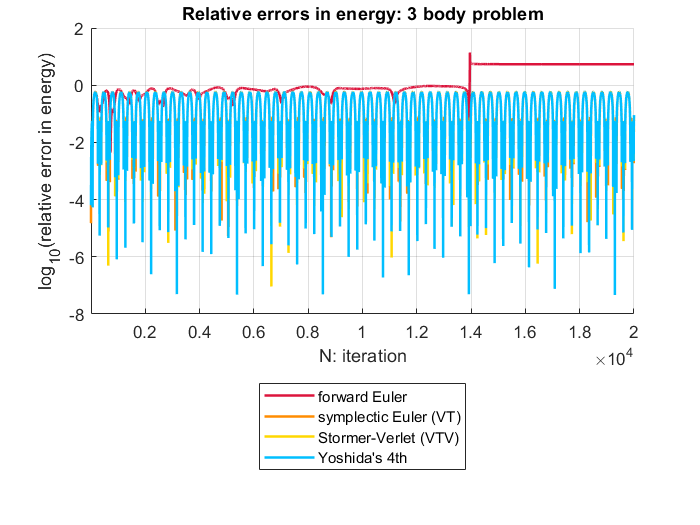

figure("Name", "Relative errors in energy"); hold on; grid on;
xlim([1, data.N+1])
xlabel("N: iteration")
ylabel("log_{10}(relative error in energy)")

if problem == "osc"
    title('Relative errors in energy: harmonic oscillator')
elseif problem == "pen"
    title('Relative errors in energy: mathematical pendulum')
elseif problem == "kep"
    title('Relative errors in energy: Kepler')
elseif problem == "3bp"
    title('Relative errors in energy: 3 body problem')
end

% Forward Euler's relative error
p_ererror_fe = plot(1:data.N+1, log10(abs(energy_fe - energy_ex)/abs(energy_ex)),...
    "Color", [220/255 20/255 60/255], "LineWidth", 1.5);

% Symplectic Euler's relative error
p_ererror_se = plot(1:data.N+1, log10(abs(energy_se - energy_ex)/abs(energy_ex)),...
    "Color", [1 140/255 0], "LineWidth", 1.5);

% Stormer-Verlet's relative error
p_ererror_sv = plot(1:data.N+1, log10(abs(energy_sv - energy_ex)/abs(energy_ex)),...
    "Color", [1 215/255 0], "LineWidth", 1.5);

% Yoshida 4th's relative error
p_ererror_y4 = plot(1:data.N+1, log10(abs(energy_y4 - energy_ex)/abs(energy_ex)),...
    "Color", [0 191/255 1], "LineWidth", 1.5);


legend([p_ererror_fe, p_ererror_se, p_ererror_sv, p_ererror_y4], ["forward Euler",...
    "symplectic Euler (VT)", "Stormer-Verlet (VTV)", "Yoshida's 4th"], "Location", "southoutside")
hold off;

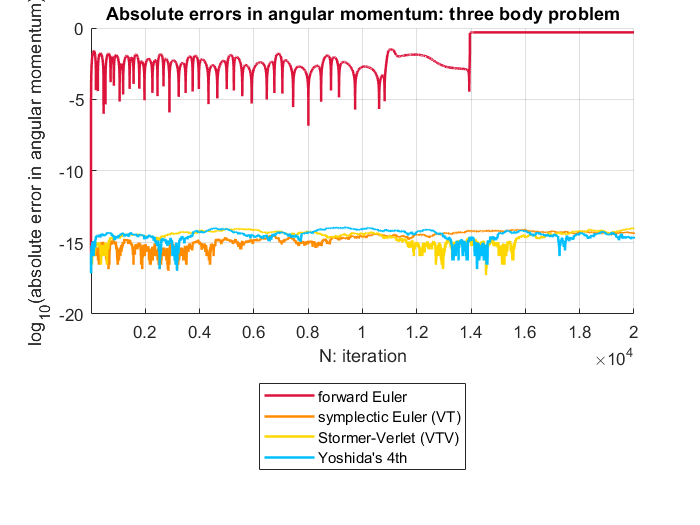


% Second conserved quantity for the n body problem: angular momentum
if problem == "kep"
    figure("Name", "Relative errors in angular momentum"); hold on; grid on;
    xlim([1, data.N+1])
    xlabel("N: iteration")
    ylabel("log_{10}(relative error in angular momentum)")
    title('Relative errors in angular momentum: Kepler')
    
    % Forward Euler's relative error
    p_arerror_fe = plot(1:data.N+1, log10(abs(amomentum_fe - L0)/abs(L0)),...
        "Color", [220/255 20/255 60/255], "LineWidth", 1.5);
    
    % Symplectic Euler (VT)'s relative error
    p_arerror_se = plot(1:data.N+1, log10(abs(amomentum_se - L0)/abs(L0)),...
        "Color", [1 140/255 0], "LineWidth", 1.5);
    
    % Stormer-Verlet (VTV)'s relative error
    p_arerror_sv = plot(1:data.N+1, log10(abs(amomentum_sv - L0)/abs(L0)),...
        "Color", [1 215/255 0], "LineWidth", 1.5);
    
    % Stormer-Verlet (VTV)'s relative error
    p_arerror_y4 = plot(1:data.N+1, log10(abs(amomentum_y4 - L0)/abs(L0)),...
        "Color", [0 191/255 1], "LineWidth", 1.5);
    
    legend([p_arerror_fe, p_arerror_se, p_arerror_sv, p_arerror_y4], ...
        ["forward Euler", "symplectic Euler (VT)", "Stormer-Verlet (VTV)",...
        "Yoshida's 4th"], "Location", "southoutside")
    hold off;
elseif problem == "3bp"
    figure("Name", "Absolute errors in angular momentum"); hold on; grid on;
    xlim([1, data.N+1])
    xlabel("N: iteration")
    ylabel("log_{10}(absolute error in angular momentum)")
    title('Absolute errors in angular momentum: three body problem')
    
    % Forward Euler's relative error
    p_arerror_fe = plot(1:data.N+1, log10(abs(Lfe(3,:) - L0(3,:))),...
        "Color", [220/255 20/255 60/255], "LineWidth", 1.5);
    
    % Symplectic Euler (VT)'s relative error
    p_arerror_se = plot(1:data.N+1, log10(abs(Lse(3,:) - L0(3,:))),...
        "Color", [1 140/255 0], "LineWidth", 1.5);
    
    % Stormer-Verlet (VTV)'s relative error
    p_arerror_sv = plot(1:data.N+1, log10(abs(Lsv(3,:) - L0(3,:))),...
        "Color", [1 215/255 0], "LineWidth", 1.5);
    
    % Stormer-Verlet (VTV)'s relative error
    p_arerror_y4 = plot(1:data.N+1, log10(abs(Ly4(3,:) - L0(3,:))),...
        "Color", [0 191/255 1], "LineWidth", 1.5);
    
    legend([p_arerror_fe, p_arerror_se, p_arerror_sv, p_arerror_y4], ...
        ["forward Euler", "symplectic Euler (VT)", "Stormer-Verlet (VTV)",...
        "Yoshida's 4th"], "Location", "southoutside")
    hold off;
end

## Time

We compute how much time has ellapsed since running this program.

run_time = toc;
fprintf("\n>> %f seconds have passed since running this code.\n", run_time)


>> 58.072214 seconds have passed since running this code.
